# EMT Basic Functionalities

## **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'L-Town.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {v2.2.4 - Last Update: 08/12/2022}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "L-Town.inp"...
Input File "L-Town.inp" loaded successfully.


G =   epanet with properties:

                                   ph: [1×1 lib.pointer]
                   ControlLevelValues: [3.9000 2.4000]
                     ControlLinkIndex: [906 906]
                     ControlNodeIndex: [785 785]
                         ControlRules: []
                    ControlRulesCount: 2
                             Controls: [1×2 struct]
                      ControlSettings: [0 1]
                         ControlTypes: {'HIGHLEVEL'  'LOWLEVEL'}
                    ControlTypesIndex: [1 0]
                           CurveCount: 1
                           CurveIndex: 1
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
  

## Data and Methods in Toolkit

What data variables are in the object?

properties(G)

Properties for class epanet:

    ph
    ControlLevelValues
    ControlLinkIndex
    ControlNodeIndex
    ControlRules
    ControlRulesCount
    Controls
    ControlSettings
    ControlTypes
    ControlTypesIndex
    CurveCount
    CurveIndex
    CurvesInfo
    DemandModelCode
    DemandModelPmin
    DemandModelPreq
    DemandModelPexp
    DemandModelType
    EnergyEfficiencyUnits
    EnergyUnits
    Errcode
    InputFile
    Iterations
    LibEPANET
    LibEPANETpath
    libFunctions
    LinkBulkReactionCoeff
    LinkCount
    LinkDiameter
    LinkFlowUnits
    LinkFrictionFactorUnits
    LinkIndex
    LinkInitialSetting
    LinkInitialStatus
    LinkLength
    LinkLengthsUnits
    LinkMinorLossCoeff
    LinkMinorLossCoeffUnits
    LinkNameID
    LinkPipeCount
    LinkPipeDiameterUnits
    LinkPipeIndex
    LinkPipeNameID
    LinkPipeRoughnessCoeffUnits
    LinkPumpCount
    LinkPumpHeadCurveIndex
    LinkPumpIndex
    LinkPumpNameID
    LinkPumpPatternIndex
    LinkPumpPatternNameID


What methods/functions are in the toolkit? 

methods(G) 

Methods for class epanet:

BinClose                                     getOptionsPipeBulkReactionOrder              
BinUpdateClass                               getOptionsPipeWallReactionOrder              
Binplot                                      getOptionsQualityTolerance                   
addBinCVPipe                                 getOptionsSpecificDiffusivity                
addBinControl                                getOptionsSpecificGravity                    
addBinCurveEfficiency                        getOptionsSpecificViscosity                  
addBinCurveHeadloss                          getOptionsTankBulkReactionOrder              
addBinCurvePump                              getPattern                                   
addBinCurveVolume                            getPatternAverageValue                       
addBinLinkPipe                               getPatternComment                            
addBinLinkPump                               getPatternCount   

 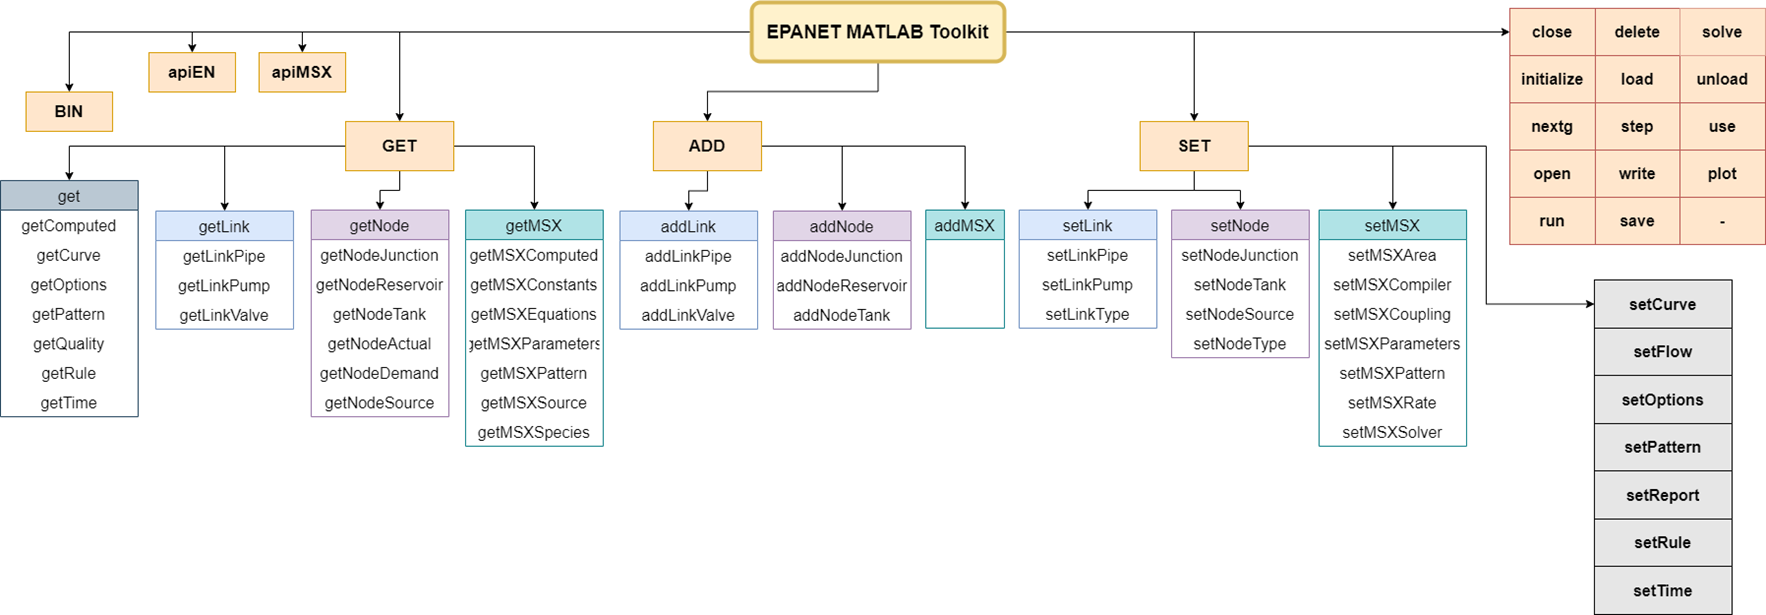

## **Need help?**

**Just type "help" followed by the command**

help G.getLinkDiameter

--- help for epanet/getLinkDiameter ---

  Retrieves the value of link diameters.
  Pipe/valve diameter
 
  Example 1:
     d.getLinkDiameter      % Retrieves the value of all link diameters
 
  Example 2:
     d.getLinkDiameter(1)   % Retrieves the value of the first link diameter
 
  See also getLinkType, getLinksInfo, getLinkLength,
           getLinkRoughnessCoeff, getLinkMinorLossCoeff.



help G.setNodeBaseDemands

--- help for epanet/setNodeBaseDemands ---

  Sets the values of demand for nodes.
 
  The examples are based on d=epanet('BWSN_Network_1.inp');
 
  Example 1:
    index_node = 1;
    d.getNodeBaseDemands{1}(index_node)                       % Retrieves the demand of the 1st node
    demand = 5;
    d.setNodeBaseDemands(index_node, demand);                 % Sets the demand of the 1st node
    d.getNodeBaseDemands{1}(index_node)
 
  Example 2:
    nodeIndex = 1:5;
    d.getNodeBaseDemands{1}(nodeIndex)                        % Retrieves the demands of first 5 nodes
    demands = [10, 5, 15, 20, 5];
    d.setNodeBaseDemands(nodeIndex, demands)                  % Sets the demands of first 5 nodes
    d.getNodeBaseDemands{1}(nodeIndex)
 
  Example 3:
    demands = d.getNodeBaseDemands{1};                        % Retrieves the demands of all nodes
    demands_new = demands + 15;
    d.setNodeBaseDemands(demands_new);     

**Exercise: Ask help for any EMT method**

% write "G." and press "Tab" key to find a command
G.getNodeCoordinates

ans = 1×4 cell array
    {[138.2200 274.2300 271.2800 186.6200 158.9300 261.3300 369.9700 162.6500 256.5400 361.4500 167.1400 271.0900 170.6800 302.2400 344.8400 336.3700 177.1200 331.1600 439.9100 325.7800 181.2200 525.8300 314.6600 393.3000 195.9500 309.6600 378.8400 305.9400 482.9700 575.5500 361.5100 478.0900 300.2900 423.9100 292.4000 525.8900 405.0300 288.8200 389.4500 370.2900 566.5300 403.7600 432.6500 526.1600 460.3400 574.8600 570.9000 617.9500 519.1300 727 445.9400 512.2800 444.7600 621.8000 777.6700 566.9900 609.2900 526.2000 768.7100 716.9300 725.8700 724.9500 761.1200 722.9500 760.6700 722.2900 719.5300 906.2400 674.2000 716.3600 745.5800 855.0400 856.1400 857.3700 975.5800 861.8900 954.1600 866.2900 946.9000 869.0800 943.9100 1.0633e+03 1.0425e+03 954.1900 1.1425e+03 1161 1.1291e+03 1.1267e+03 1.0978e+03 1.1901e+03 1.1401e+03 1.1632e+03 1.2928e+03 280.5500 226.1600 215.2900 331.4200 281.8800 208.6800 329.9300 290.4700 275.5500 313.2000 171.0100 332.6400 274.4500 314.2500

## **Plot network topology**

## 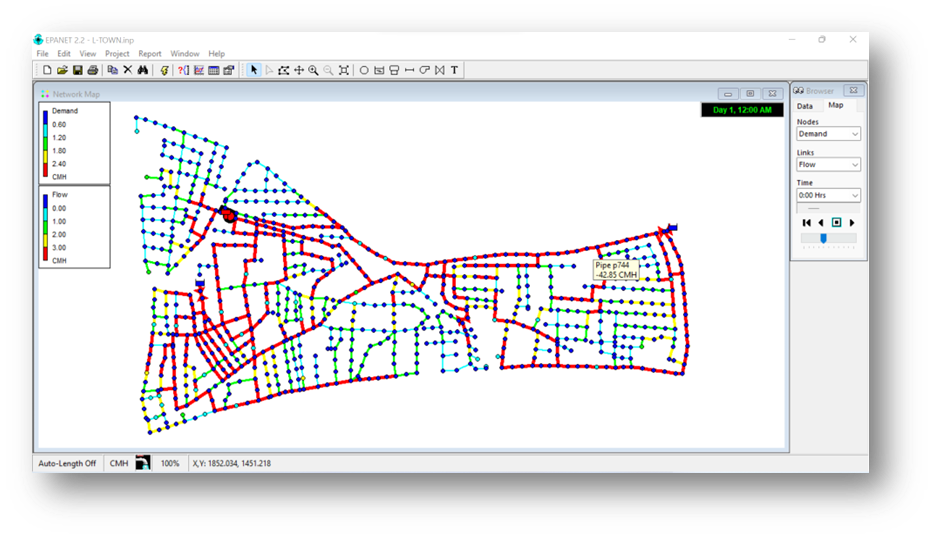

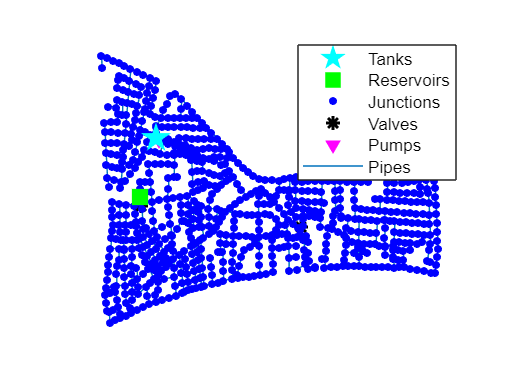

% For a simple plot, use G.plot. 
G.plot;

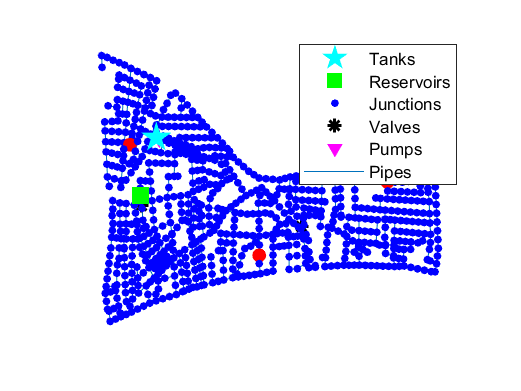

% Highlight specific nodes
G.plot('highlightnode',{'n616', 'n281', 'n31'});

## **Getting information from links (pipes,pumps,valves)**

## 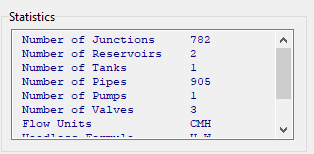

linkCount = G.getLinkCount

linkCount = int32
909

pipeCount = G.getLinkPipeCount

pipeCount = 905

pumpCount = G.getLinkPumpCount

pumpCount = 1

valveCount = G.getLinkValveCount

valveCount = int32
3

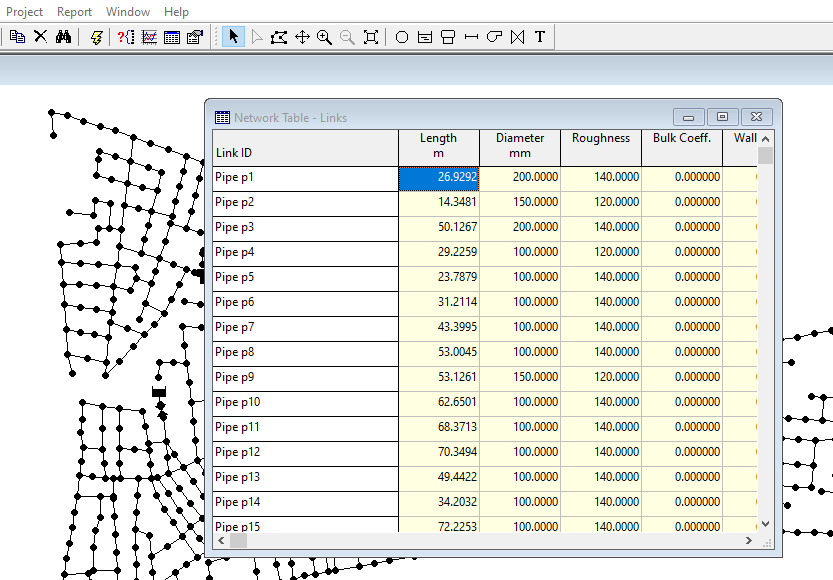

diameters = G.getLinkDiameter

diameters =    200   150   200   100   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


pipelength = G.getLinkLength(1:3)

pipelength =    26.9292   14.3481   50.1267


LinkNameID = G.getLinkNameID

LinkNameID = 1×909 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p8

PipeNameID = G.getLinkPipeNameID

PipeNameID = 1×905 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p8

PumpNameID = G.getLinkPumpNameID

PumpNameID = 1×1 cell array
    {'PUMP_1'}


ValveNameID = G.getLinkValveNameID

ValveNameID = 1×3 cell array
    {'PRV-1'}    {'PRV-2'}    {'PRV-3'}


## **Getting information from nodes (junctions,tanks,reservoirs)**

## 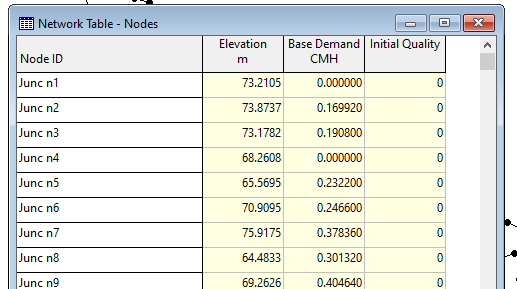

nodeCount = G.getNodeCount

nodeCount = int32
785

junctionCount = G.getNodeJunctionCount

junctionCount = int32
782

tankCount = G.getNodeTankCount

tankCount = 1

reservoirCount = G.getNodeReservoirCount

reservoirCount = 2

elevations = G.getNodeElevations([1, 2, 3])

elevations =    73.2105   73.8737   73.1782



nodeID = G.getNodeNameID

nodeID = 1×785 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}    

junctionID = G.getNodeJunctionNameID

junctionID = 1×782 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}

tankID = G.getNodeTankNameID

tankID = 1×1 cell array
    {'T1'}


reservoirID = G.getNodeReservoirNameID

reservoirID = 1×2 cell array
    {'R1'}    {'R2'}



%% Try it yourself below
base_Demands = G.getNodeBaseDemands

base_Demands = 1×3 cell array
    {[0 0.1699 0.1908 0 0.2322 0.2466 0.3784 0.3013 0.4046 0.0842 0.5443 0.0583 0.2358 0.0194 0.1915 0.0965 0.4489 0.0724 0.1292 0.1444 0.0608 0.1508 0.0287 0.0439 0 0.0047 0.1307 0 0.0490 0.3056 0.1163 0.0799 0.0029 0.1123 0 0.2664 0.0846 0.1889 0.0166 0.3420 0.1703 0.2430 0.1181 0.0389 0.2729 0.0697 0.1462 0.2178 0.1036 0.3899 0.3334 0.0489 0.2995 0.0848 0.2535 0.3182 0.0681 0.1637 0.1348 0.0875 0.0263 0.0791 0.1559 0.1569 0.0424 0.0733 0.4047 0.1781 0.3772 0.1782 0.2418 0.0195 0.0315 0.0491 0.0244 0.0975 0.0295 0.0999 0.1827 0.2583 0.1722 0.1761 0.1530 0.1419 0.0011 0.1820 0.0061 0.0770 0.0181 0.1069 0.0133 0.0157 0.1611 0.5347 0 0.1387 0.4247 0.1231 0.1717 0.3638 0.1260 0.0945 0.0847 0 0.0014 0.1120 7.4000e-04 0 5.7800e-04 0.0280 0.3689 0.1171 0.1257 0.0824 0.0065 0.1902 0.2583 0 0.2426 0.0850 2.4000e-04 0.1017 0.1344 0.0119 0.0500 0.2380 0.0060 0.1118 0.1420 0.2047 0.1182 0.1321 0.2793 0.0090 0.1132 0.3360 0.0368 0.0273 0 0.1167 0.2161 0.0399 0.1240 0

## **Demands**

 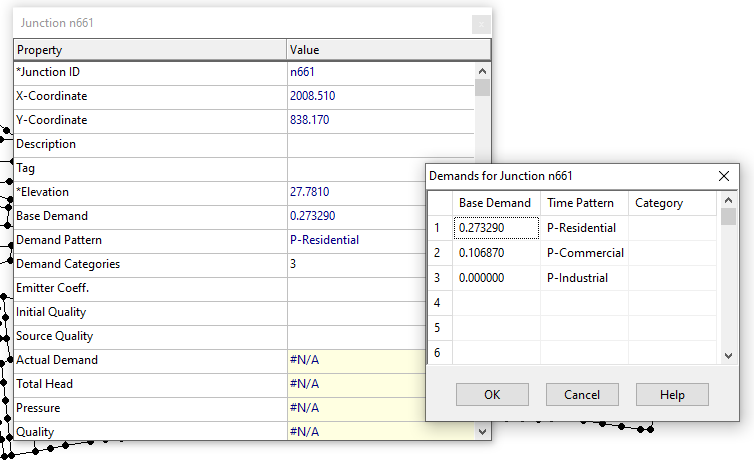

demandcategories = G.getNodeDemandCategoriesNumber

demandcategories =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


demands = G.getNodeBaseDemands

demands = 1×3 cell array
    {[0 0.1699 0.1908 0 0.2322 0.2466 0.3784 0.3013 0.4046 0.0842 0.5443 0.0583 0.2358 0.0194 0.1915 0.0965 0.4489 0.0724 0.1292 0.1444 0.0608 0.1508 0.0287 0.0439 0 0.0047 0.1307 0 0.0490 0.3056 0.1163 0.0799 0.0029 0.1123 0 0.2664 0.0846 0.1889 0.0166 0.3420 0.1703 0.2430 0.1181 0.0389 0.2729 0.0697 0.1462 0.2178 0.1036 0.3899 0.3334 0.0489 0.2995 0.0848 0.2535 0.3182 0.0681 0.1637 0.1348 0.0875 0.0263 0.0791 0.1559 0.1569 0.0424 0.0733 0.4047 0.1781 0.3772 0.1782 0.2418 0.0195 0.0315 0.0491 0.0244 0.0975 0.0295 0.0999 0.1827 0.2583 0.1722 0.1761 0.1530 0.1419 0.0011 0.1820 0.0061 0.0770 0.0181 0.1069 0.0133 0.0157 0.1611 0.5347 0 0.1387 0.4247 0.1231 0.1717 0.3638 0.1260 0.0945 0.0847 0 0.0014 0.1120 7.4000e-04 0 5.7800e-04 0.0280 0.3689 0.1171 0.1257 0.0824 0.0065 0.1902 0.2583 0 0.2426 0.0850 2.4000e-04 0.1017 0.1344 0.0119 0.0500 0.2380 0.0060 0.1118 0.1420 0.2047 0.1182 0.1321 0.2793 0.0090 0.1132 0.3360 0.0368 0.0273 0 0.1167 0.2161 0.0399 0.1240 0.3396

demandscategory1 = G.getNodeBaseDemands{2} % Get categories 1

demandscategory1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1052         0         0    0.0238         0    0.3928         0         0         0         0    0.1195         0    0.0533         0         0    0.3255         0         0         0         0         0         0         0    0.0077    0.0626    0.0032    0.0098    0.1865



NodeIndex = G.getNodeIndex('n661')   % Retrieves the node index given the ID label of the node

NodeIndex = int32
661

G.getNodeBaseDemands(NodeIndex)   % Get node base demand with categories for specific node index

ans = 1×3 cell array
    {[0.2733]}    {[0.1069]}    {[0]}


## **Change parameters in network**

**Change diameter**

%change pipe diameter
d4 = G.getLinkDiameter(4)

d4 = 100

diameters = G.getLinkDiameter

diameters =    200   150   200   100   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


diameters(4) = 200

diameters =    200   150   200   200   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


G.setLinkDiameter(diameters)
d4new = G.getLinkDiameter(4)

d4new = 200

**Change elevation**

%change node elevation
e4 = G.getNodeElevations(4)

e4 = 68.2608

elevations = G.getNodeElevations

elevations =    73.2105   73.8737   73.1782   68.2608   65.5695   70.9095   75.9175   64.4833   69.2626   74.3469   63.0588   68.2274   61.9901   68.5805   70.9492   68.7986   60.5935   67.1420   73.3626   65.9549   59.6849   76.1173   64.2052   67.8217   58.9717   61.6305   65.7763   61.4047   71.5429   75.3299   65.0059   71.1590   60.5902   65.8482   59.6258   70.1959   63.9172   58.5794   62.9791   60.2093   69.2961   61.0635   61.8585   66.1177   62.5989   38.8781   38.7028   40.1135   34.8665   44.7174


elevations(4) = 70

elevations =    73.2105   73.8737   73.1782   70.0000   65.5695   70.9095   75.9175   64.4833   69.2626   74.3469   63.0588   68.2274   61.9901   68.5805   70.9492   68.7986   60.5935   67.1420   73.3626   65.9549   59.6849   76.1173   64.2052   67.8217   58.9717   61.6305   65.7763   61.4047   71.5429   75.3299   65.0059   71.1590   60.5902   65.8482   59.6258   70.1959   63.9172   58.5794   62.9791   60.2093   69.2961   61.0635   61.8585   66.1177   62.5989   38.8781   38.7028   40.1135   34.8665   44.7174


G.setNodeElevations(elevations)
e4new = G.getNodeElevations(4)

e4new = 70

## **Patterns**

G.getPatternCount

ans = int32
5

PatternsNames = G.getPatternNameID

PatternsNames = 1×5 cell array
    {'P-Residential'}    {'P-Commercial'}    {'P-Industrial'}    {'vxdxq'}    {'choyz'}


Patterns = G.getPattern

Patterns =     0.7729    0.7480    0.7230    0.6986    0.6751    0.6525    0.6305    0.6089    0.5874    0.5659    0.5446    0.5236    0.5031    0.4833    0.4643    0.4459    0.4279    0.4103    0.3929    0.3757    0.3590    0.3430    0.3279    0.3139    0.3013    0.2899    0.2795    0.2700    0.2610    0.2523    0.2439    0.2355    0.2273    0.2192    0.2114    0.2042    0.1976    0.1918    0.1868    0.1827    0.1794    0.1765    0.1738    0.1710    0.1678    0.1642    0.1602    0.1561    0.1522    0.1490
    0.9174    0.9053    0.8929    0.8802    0.8673    0.8541    0.8406    0.8269    0.8128    0.7988    0.7848    0.7714    0.7585    0.7465    0.7351    0.7242    0.7136    0.7029    0.6919    0.6807    0.6693    0.6580    0.6473    0.6374    0.6287    0.6211    0.6146    0.6088    0.6034    0.5980    0.5923    0.5862    0.5797    0.5730    0.5663    0.5600    0.5543    0.5492    0.5449    0.5411    0.5378    0.5348    0.5320    0.5294    0.5268    0.5244    0.5222    0.5203    0.51

**Plot residential pattern**

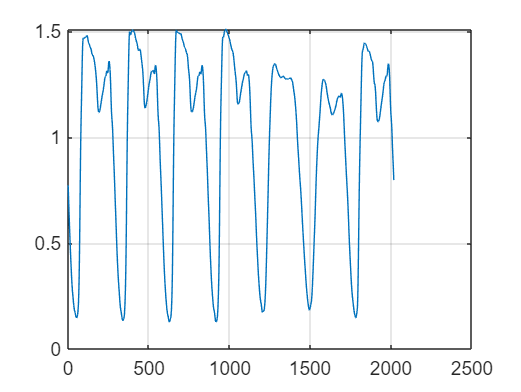

figure
plot(Patterns(1,:)); grid on

## 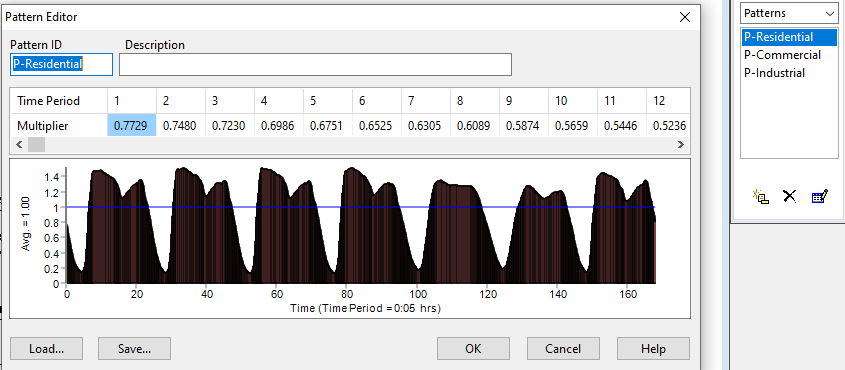

%adding a pattern (name is string of 5 random letters a-z)
patternID = char(randi([97 122],1,5)) 

patternID = 'ezymu'

patternMult = Patterns(2,:)*0.5

patternMult =     0.4587    0.4527    0.4464    0.4401    0.4336    0.4270    0.4203    0.4135    0.4064    0.3994    0.3924    0.3857    0.3792    0.3733    0.3675    0.3621    0.3568    0.3514    0.3460    0.3404    0.3347    0.3290    0.3237    0.3187    0.3144    0.3106    0.3073    0.3044    0.3017    0.2990    0.2961    0.2931    0.2898    0.2865    0.2831    0.2800    0.2772    0.2746    0.2725    0.2706    0.2689    0.2674    0.2660    0.2647    0.2634    0.2622    0.2611    0.2601    0.2593    0.2586


patternIndex = G.addPattern(patternID, patternMult)

patternIndex = int32
6

Patterns = G.getPattern

Patterns =     0.7729    0.7480    0.7230    0.6986    0.6751    0.6525    0.6305    0.6089    0.5874    0.5659    0.5446    0.5236    0.5031    0.4833    0.4643    0.4459    0.4279    0.4103    0.3929    0.3757    0.3590    0.3430    0.3279    0.3139    0.3013    0.2899    0.2795    0.2700    0.2610    0.2523    0.2439    0.2355    0.2273    0.2192    0.2114    0.2042    0.1976    0.1918    0.1868    0.1827    0.1794    0.1765    0.1738    0.1710    0.1678    0.1642    0.1602    0.1561    0.1522    0.1490
    0.9174    0.9053    0.8929    0.8802    0.8673    0.8541    0.8406    0.8269    0.8128    0.7988    0.7848    0.7714    0.7585    0.7465    0.7351    0.7242    0.7136    0.7029    0.6919    0.6807    0.6693    0.6580    0.6473    0.6374    0.6287    0.6211    0.6146    0.6088    0.6034    0.5980    0.5923    0.5862    0.5797    0.5730    0.5663    0.5600    0.5543    0.5492    0.5449    0.5411    0.5378    0.5348    0.5320    0.5294    0.5268    0.5244    0.5222    0.5203    0.51

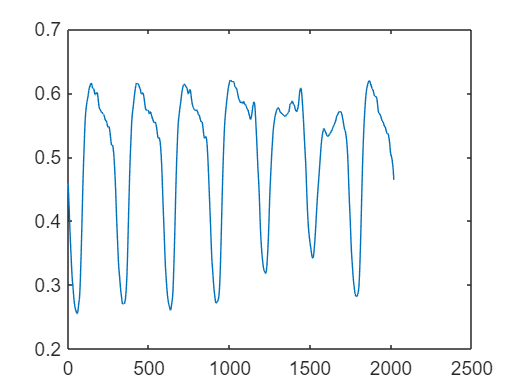

%plot new pattern
figure
plot(Patterns(patternIndex,:))

## **Simulation options**

**Time options**

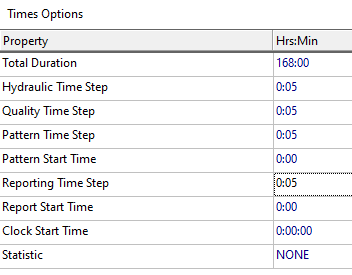

SimulationDuration = G.getTimeSimulationDuration %in seconds

SimulationDuration = int32
604800

SimulationDurationHours = SimulationDuration/3600

SimulationDurationHours = int32
168


HydraulicStep = G.getTimeHydraulicStep %in seconds

HydraulicStep = int32
300

QualityStep = G.getTimeQualityStep %in seconds

QualityStep = int32
300

PatternStep = G.getTimePatternStep %in seconds

PatternStep = int32
300


ReportingStep = G.getTimeReportingStep %in seconds

ReportingStep = int32
300

ReportingStart = G.getTimeReportingStart

ReportingStart = int32
0

PatternStart = G.getTimePatternStart

PatternStart = int32
0

**Hydraulic options**

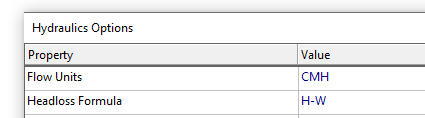

Units = G.getUnits

Units = struct with fields:
                    Units_SI_Metric: 1
                 Units_US_Customary: 0
                      LinkFlowUnits: 'CMH'
                  NodePressureUnits: 'meters'
                PatternDemandsUnits: 'CMH'
              LinkPipeDiameterUnits: 'millimeters'
              NodeTankDiameterUnits: 'meters'
              EnergyEfficiencyUnits: 'percent'
                 NodeElevationUnits: 'meters'
                    NodeDemandUnits: 'CMH'
        NodeEmitterCoefficientUnits: 'flow units @ 1 meter drop'
                        EnergyUnits: 'kwatt-hours'
            LinkFrictionFactorUnits: 'unitless'
                      NodeHeadUnits: 'meters'
                   LinkLengthsUnits: 'meters'
            LinkMinorLossCoeffUnits: 'unitless'
                 LinkPumpPowerUnits: 'kwatts'
      QualityReactionCoeffBulkUnits: '1/day (1st-order)'
      QualityReactionCoeffWallUnits: 'mass/sq-m/day(0-order), meters/day (1st-order)'
        LinkPipeRoughnessCoeffUnits:

FlowUnits = G.getFlowUnits

FlowUnits = 'CMH'

PressureUnits = G.NodePressureUnits

PressureUnits = 'meters'

HeadLossFormula = G.getOptionsHeadLossFormula

HeadLossFormula = 'HW'

**Setup quality options**

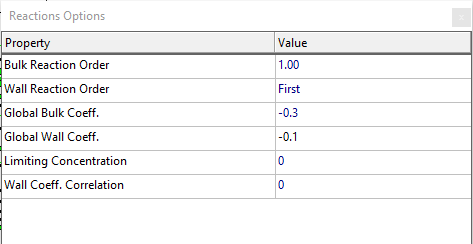

G.setQualityType('chlorine','mg/L') %set quality type

zeroNodes = zeros(1,G.NodeCount)

zeroNodes =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


G.setNodeInitialQuality(zeroNodes) %setting initial chlorine level at 0  mg/L

brk = -0.3 * ones(1,G.LinkCount)

brk =    -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000   -0.3000


G.setLinkBulkReactionCoeff(brk) %setting Bulk Reaction Coefficient

wrk = -0.1 * ones(1,G.LinkCount)

wrk =    -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000   -0.1000


G.setLinkWallReactionCoeff(wrk) %setting Pipe wall Reaction Coefficient

BulkReactionOrder = G.getOptionsPipeBulkReactionOrder

BulkReactionOrder = single
1

PipeWallReactionOrder = G.getOptionsPipeWallReactionOrder

PipeWallReactionOrder = single
1

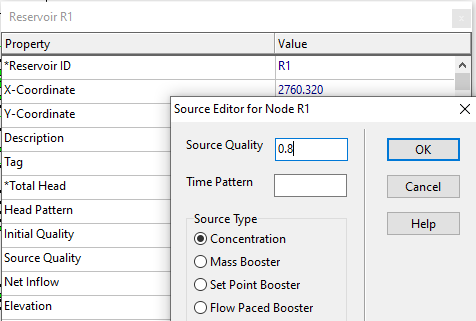

ReservoirsIndex = G.getNodeReservoirIndex

ReservoirsIndex =    783   784


help G.setNodeSourceType

--- help for epanet/setNodeSourceType ---

  Sets the values of quality source type.
 
  Types of external water quality sources that can be set:
    1) CONCEN      Sets the concentration of external inflow entering a node
    2) MASS        Injects a given mass/minute into a node
    3) SETPOINT    Sets the concentration leaving a node to a given value
    4) FLOWPACED   Adds a given value to the concentration leaving a node
 
  Example:
    nodeIndex = 1;
    d.getNodeSourceType{nodeIndex}               % Retrieves the quality source type of the 1st node
    sourceType = 'MASS';
    d.setNodeSourceType(nodeIndex, sourceType)   % Sets the quality source type = 'MASS' to the 1st node
    d.getNodeSourceType{nodeIndex}
 
  See also getNodeSourceType, setNodeSourceQuality, 


for i=1:length(ReservoirsIndex) %number of reservoirs
    G.setNodeSourceType(ReservoirsIndex(i), 'CONCEN')
    G.setNodeSourceQuality(ReservoirsIndex(i),0.8)
end

NodeSourceQuality = G.getNodeSourceQuality(ReservoirsIndex)

NodeSourceQuality =     0.8000    0.8000
